Data 

x = [1 3 4.5 6 8 11 13 14];
y = [2 3 3.5 2.8 4 3.5 3.4 3];

plot(x,y,'ko')
hold on
axis([-2 18 0 6])

Linear spline

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


yy = interp1(x,y,xx,"linear")

yy =     2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0333    3.0667    3.1000    3.1333    3.1667    3.2000    3.2333    3.2667    3.3000    3.3333    3.3667    3.4000    3.4333    3.4667    3.5000    3.4533    3.4067    3.3600    3.3133    3.2667    3.2200    3.1733    3.1267    3.0800    3.0333    2.9867    2.9400    2.8933    2.8467


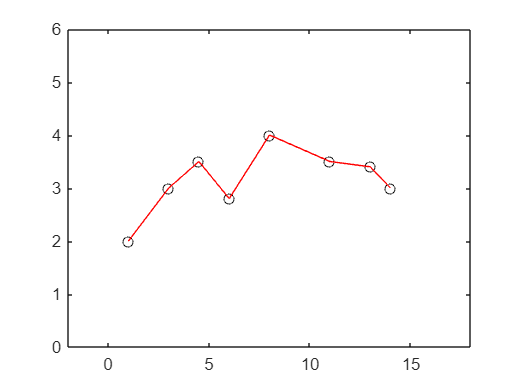


plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 0 6])

Quadratic spline

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


yy = quspline(x,y,xx)

yy =     2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0300    3.0533    3.0700    3.0800    3.0833    3.0800    3.0700    3.0533    3.0300    3.0000    2.9633    2.9200    2.8700    2.8133    3.5000    3.4511    3.3978    3.3400    3.2778    3.2111    3.1400    3.0644    2.9844    2.9000    2.8111    2.7178    2.6200    2.5178    2.4111


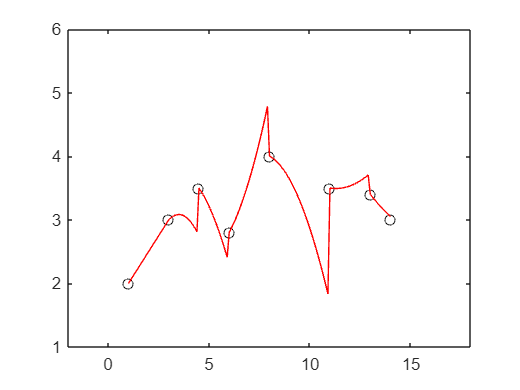


plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 1 6])

Cubic spline (natural spline)

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


yy = natspline(x,y,xx)

yy =     2.0000    2.0463    2.0927    2.1392    2.1859    2.2328    2.2799    2.3274    2.3753    2.4236    2.4724    2.5218    2.5717    2.6224    2.6737    2.7259    2.7788    2.8326    2.8874    2.9432    3.0000    3.0578    3.1158    3.1732    3.2291    3.2826    3.3330    3.3793    3.4207    3.4563    3.4852    3.5066    3.5197    3.5235    3.5172    3.5000    3.4714    3.4327    3.3856    3.3319    3.2734    3.2117    3.1485    3.0857    3.0249    2.9679    2.9164    2.8721    2.8368    2.8122


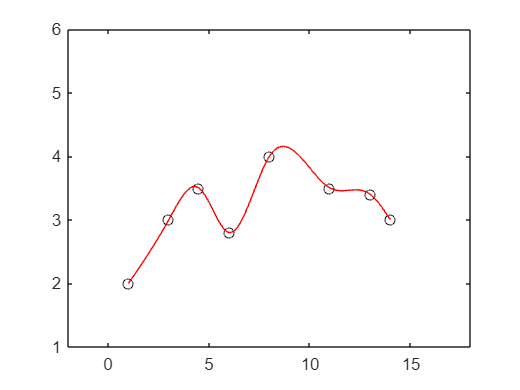

% yy = interp1(x,y,xx,"spline")


plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 1 6])

Cubic spline (using interp1)

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


% yy = natspline(x,y,xx)
yy = interp1(x,y,xx,"spline")

yy =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111


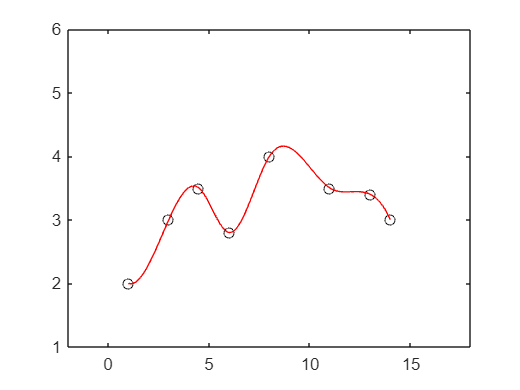



plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 1 6])

Cubic spline (using spline)

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


% yy = natspline(x,y,xx)
yy = spline(x,y,xx)

yy =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111




plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 1 6])

Cubic spline (using spline & ppval)

xx = 1 : 0.1 : 14

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


cs = spline(x,y)

cs = struct with fields:
      form: 'pp'
    breaks: [1 3 4.5000 6 8 11 13 14]
     coefs: [7×4 double]
    pieces: 7
     order: 4
       dim: 1


yy = ppval(cs,xx)

yy =     2.0000    1.9941    1.9978    2.0103    2.0311    2.0597    2.0953    2.1373    2.1853    2.2385    2.2964    2.3584    2.4239    2.4922    2.5628    2.6350    2.7083    2.7821    2.8557    2.9285    3.0000    3.0695    3.1365    3.2003    3.2604    3.3161    3.3668    3.4119    3.4509    3.4830    3.5078    3.5247    3.5329    3.5319    3.5212    3.5000    3.4682    3.4271    3.3783    3.3235    3.2644    3.2026    3.1397    3.0775    3.0177    2.9617    2.9115    2.8685    2.8345    2.8111




plot(x,y,'ko')
hold on

plot(xx,yy,'r-')
hold off
axis([-2 18 1 6])

Cubic spline (plot each segment with different colors)

seg1 = linspace(x(1),x(2))

seg1 =     1.0000    1.0202    1.0404    1.0606    1.0808    1.1010    1.1212    1.1414    1.1616    1.1818    1.2020    1.2222    1.2424    1.2626    1.2828    1.3030    1.3232    1.3434    1.3636    1.3838    1.4040    1.4242    1.4444    1.4646    1.4848    1.5051    1.5253    1.5455    1.5657    1.5859    1.6061    1.6263    1.6465    1.6667    1.6869    1.7071    1.7273    1.7475    1.7677    1.7879    1.8081    1.8283    1.8485    1.8687    1.8889    1.9091    1.9293    1.9495    1.9697    1.9899


seg2 = linspace(x(2),x(3))

seg2 =     3.0000    3.0152    3.0303    3.0455    3.0606    3.0758    3.0909    3.1061    3.1212    3.1364    3.1515    3.1667    3.1818    3.1970    3.2121    3.2273    3.2424    3.2576    3.2727    3.2879    3.3030    3.3182    3.3333    3.3485    3.3636    3.3788    3.3939    3.4091    3.4242    3.4394    3.4545    3.4697    3.4848    3.5000    3.5152    3.5303    3.5455    3.5606    3.5758    3.5909    3.6061    3.6212    3.6364    3.6515    3.6667    3.6818    3.6970    3.7121    3.7273    3.7424


seg3 = linspace(x(3),x(4))

seg3 =     4.5000    4.5152    4.5303    4.5455    4.5606    4.5758    4.5909    4.6061    4.6212    4.6364    4.6515    4.6667    4.6818    4.6970    4.7121    4.7273    4.7424    4.7576    4.7727    4.7879    4.8030    4.8182    4.8333    4.8485    4.8636    4.8788    4.8939    4.9091    4.9242    4.9394    4.9545    4.9697    4.9848    5.0000    5.0152    5.0303    5.0455    5.0606    5.0758    5.0909    5.1061    5.1212    5.1364    5.1515    5.1667    5.1818    5.1970    5.2121    5.2273    5.2424


seg4 = linspace(x(4),x(5))

seg4 =     6.0000    6.0202    6.0404    6.0606    6.0808    6.1010    6.1212    6.1414    6.1616    6.1818    6.2020    6.2222    6.2424    6.2626    6.2828    6.3030    6.3232    6.3434    6.3636    6.3838    6.4040    6.4242    6.4444    6.4646    6.4848    6.5051    6.5253    6.5455    6.5657    6.5859    6.6061    6.6263    6.6465    6.6667    6.6869    6.7071    6.7273    6.7475    6.7677    6.7879    6.8081    6.8283    6.8485    6.8687    6.8889    6.9091    6.9293    6.9495    6.9697    6.9899


seg5 = linspace(x(5),x(6))

seg5 =     8.0000    8.0303    8.0606    8.0909    8.1212    8.1515    8.1818    8.2121    8.2424    8.2727    8.3030    8.3333    8.3636    8.3939    8.4242    8.4545    8.4848    8.5152    8.5455    8.5758    8.6061    8.6364    8.6667    8.6970    8.7273    8.7576    8.7879    8.8182    8.8485    8.8788    8.9091    8.9394    8.9697    9.0000    9.0303    9.0606    9.0909    9.1212    9.1515    9.1818    9.2121    9.2424    9.2727    9.3030    9.3333    9.3636    9.3939    9.4242    9.4545    9.4848


seg6 = linspace(x(6),x(7))

seg6 =    11.0000   11.0202   11.0404   11.0606   11.0808   11.1010   11.1212   11.1414   11.1616   11.1818   11.2020   11.2222   11.2424   11.2626   11.2828   11.3030   11.3232   11.3434   11.3636   11.3838   11.4040   11.4242   11.4444   11.4646   11.4848   11.5051   11.5253   11.5455   11.5657   11.5859   11.6061   11.6263   11.6465   11.6667   11.6869   11.7071   11.7273   11.7475   11.7677   11.7879   11.8081   11.8283   11.8485   11.8687   11.8889   11.9091   11.9293   11.9495   11.9697   11.9899


seg7 = linspace(x(7),x(8))

seg7 =    13.0000   13.0101   13.0202   13.0303   13.0404   13.0505   13.0606   13.0707   13.0808   13.0909   13.1010   13.1111   13.1212   13.1313   13.1414   13.1515   13.1616   13.1717   13.1818   13.1919   13.2020   13.2121   13.2222   13.2323   13.2424   13.2525   13.2626   13.2727   13.2828   13.2929   13.3030   13.3131   13.3232   13.3333   13.3434   13.3535   13.3636   13.3737   13.3838   13.3939   13.4040   13.4141   13.4242   13.4343   13.4444   13.4545   13.4646   13.4747   13.4848   13.4949


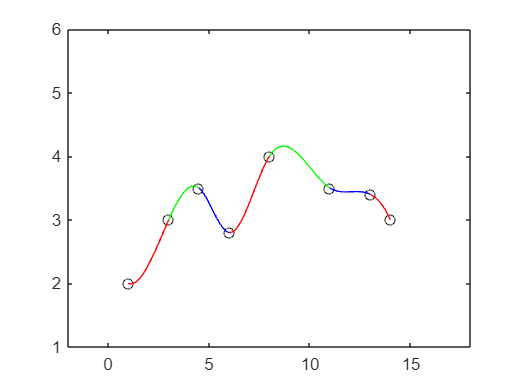


yseg1 = spline(x,y,seg1);
yseg2 = spline(x,y,seg2);
yseg3 = spline(x,y,seg3);
yseg4 = spline(x,y,seg4);
yseg5 = spline(x,y,seg5);
yseg6 = spline(x,y,seg6);
yseg7 = spline(x,y,seg7);

plot(x,y,'ko')

hold on
plot(seg1,yseg1,'r-')
plot(seg2,yseg2,'g-')
plot(seg3,yseg3,'b-')
plot(seg4,yseg4,'r-')
plot(seg5,yseg5,'g-')
plot(seg6,yseg6,'b-')
plot(seg7,yseg7,'r-')
hold off

axis([-2 18 1 6])